clear

addpath("matlab_functions\")

method = "Analytical";

#### Compute Sensitivity

if strcmpi(method, 'Analytical')
    [Plate, Coil, Sensor] = myModel;
else
    [Plate, Coil, Sensor, Model] = myModel;
    mesh_size = 2; % 1:finest 9:coarsest
end

for freq = [900 225 100 55]
    if strcmpi(method, 'Analytical')
        S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq);
    else
        S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size);
    end
    
    element_centers = Plate.elems_center;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S','element_centers')
end

Compute coil took 2.70 seconds
Compute sensor 1 took 0.43 seconds
Compute sensor 2 took 0.42 seconds
Compute sensor 3 took 0.49 seconds
Compute sensor 4 took 0.42 seconds
Compute sensor 5 took 0.47 seconds
Compute sensor 6 took 0.42 seconds
Compute sensor 7 took 0.47 seconds
Compute sensor 8 took 0.42 seconds
Compute sensor 9 took 0.48 seconds
Compute sensor 10 took 0.42 seconds
Compute sensor 11 took 0.46 seconds
Compute sensor 12 took 0.43 seconds
Compute sensor 13 took 0.46 seconds
Compute sensor 14 took 0.43 seconds
Compute sensor 15 took 0.44 seconds
Compute sensor 16 took 0.43 seconds
Compute sensor 17 took 0.42 seconds
Compute sensor 18 took 0.52 seconds
Compute sensor 19 took 0.45 seconds
Compute sensor 20 took 0.55 seconds
Compute sensor 21 took 0.45 seconds
Compute sensor 22 took 0.50 seconds
Compute sensor 23 took 0.44 seconds
Compute sensor 24 took 0.49 seconds
Compute sensor 25 took 0.45 seconds
Compute sensor 26 took 0.50 seconds
Compute sensor 27 took 0.46 seconds
Comput


clear method mesh_size freq fname element_centers

#### Visualize Sensitivity

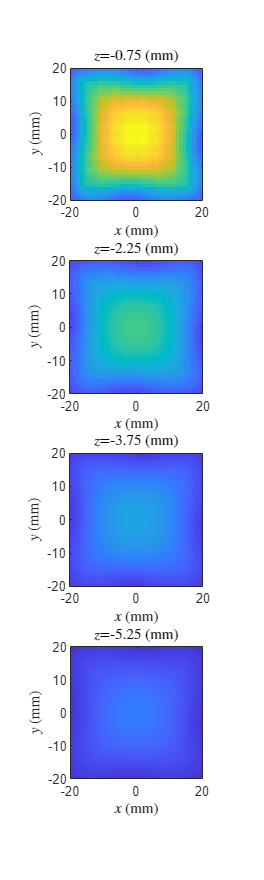

load('data\Sensitivity_100Hz_temp.mat')
VisualizeSensitivity(S, element_centers, 'all')

function S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size)

x = Plate.gauss_points(1,:,:);
y = Plate.gauss_points(2,:,:);
z = Plate.gauss_points(3,:,:);

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
ComsolModel('SolveCoil', Model, Coil, freq, mesh_size);
[Ex,Ey,Ez] = ComsolModel('InterpField', Model, {'Ex' 'Ey' 'Ez'}, x,y,z);
E1 = [Ex; Ey; Ez];
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    ComsolModel('SolveSensor', Model, Sensor, freq, mesh_size);
    [Ex,Ey,Ez] = ComsolModel('InterpField', Model, {'Ex' 'Ey' 'Ez'}, x,y,z);
    E2 = [Ex; Ey; Ez];
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

end

function S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq)

x = Plate.gauss_points(1,:,:);
y = Plate.gauss_points(2,:,:);
z = Plate.gauss_points(3,:,:);
omega = 2*pi * freq;

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
[Ex,Ey] = CoilElectricField(Coil, Plate, x, y, z, omega);
E1 = [Ex;Ey];
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    [Ex,Ey] = SensorElectricField(Sensor, Plate, x, y, z, omega);
    E2 = [Ex;Ey];
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

end

function [Ex,Ey] = CoilElectricField(Coil, Plate, x,y,z, omega)

if Coil.fillet ~= Coil.width / 2
    error('Only support cylindrical coil')
end
zc = unique(Coil.positions(3,:));
if numel(zc) ~= 1
    error('Coils must be at the same z position')
end

coil.type = 'cylindrical';
coil.r2 = Coil.width / 2;
coil.r1 = coil.r2 - Coil.thickness;
coil.z2 = zc + Coil.height / 2;
coil.z1 = zc - Coil.height / 2;
coil.N = Coil.N_turns;
coil.I = 1;

layers{1}.sigma     = Plate.conductivity;
layers{1}.mur       = Plate.relative_permeability;
layers{1}.thickness = Plate.height;
layers{2} = struct('sigma',0, 'mur',1, 'thickness',Inf);
coilAbovePlate = CoilAbovePlate2D(coil, layers);

Ex = 0;
Ey = 0;
for k = 1:size(Coil.positions,2)
    [theta,r] = cart2pol(x-Coil.positions(1,k), y-Coil.positions(2,k));
    E_theta = coilAbovePlate.EvaluateField('Etheta', r,z,omega) * Coil.current(k);
    Ex = Ex + E_theta .* -sin(theta);
    Ey = Ey + E_theta .*  cos(theta);
end

end

function [Ex,Ey] = SensorElectricField(Sensor, Plate, x,y,z, omega)

layers{1}.sigma     = Plate.conductivity;
layers{1}.mur       = Plate.relative_permeability;
layers{1}.thickness = Plate.height;
layers{2} = struct('sigma',0, 'mur',1, 'thickness',Inf);

k = Sensor.compute_index;
sensor.type = 'MagneticSensor';
sensor.position = [0 0 Sensor.positions(3,k)];
sensor.sense_axis = Sensor.axes(:,k);

sensorAbovePlate = CoilAbovePlate3D(sensor, layers);

[Ex,Ey] = sensorAbovePlate.EvaluateField({'Ex' 'Ey'}, ...
    x-Sensor.positions(1,k), y-Sensor.positions(2,k), z, omega);

end

function VisualizeSensitivity(S, element_centers, varargin)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

if isempty(varargin) || strcmpi(varargin{1}, 'all')
    S_norm = vecnorm(S);
else
    S_norm = abs(S(varargin{1},:));
end

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;

    subplot(length(z),1,k)
    imagesc(x, y, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end